## Uribe & Yue (2006)

## Table 6.1.BR, Brazil Only (Extended Data - our own compilation)

Single-country version, using our own compiled "BR_extended" sheet from Brazil_extended_data.xlsx -- Brazil only, 1994:Q1 through 2026:Q1 (129 quarters), which is both longer AND more current than every other version we've built (statadata.xls: 1994-2001; irs_data_update.mat: 1994-2012).  Because this is a single country, there's no panel/fixed-effects machinery needed: no cross-country demeaning, since there's only one group. Each equation is estimated by 2SLS with an intercept (own lag instrumented by its second lag, same identification logic as before -- though with N=119-120 quarters for one country, Nickell-style dynamic- panel bias isn't really a concern here; the IV is kept mainly for consistency with every other table in this series).

## Section 0: Setup

clear; close all; clc;
folder   = 'C:\Users\celso\Documents\FGV-EESP\Open macroeconomics\2026\Cap 6 - replication\uribe yue replication\SGU_cap6_extension_Brazil';
datafile = fullfile(folder, 'Brazil_extended_data.xlsx');

## Section 1: Load the BR_extended sheet

T = readtable(datafile, 'Sheet', 'BR_extended_values');

time      = T.time;
logydsa   = T.logydsa;
loginvdsa = T.loginvdsa;
tbysa     = T.tbysa;
logrus    = T.logrus;
logi      = T.logi;    % country interest rate R, not investment

[time, ord] = sort(time);
logydsa = logydsa(ord); loginvdsa = loginvdsa(ord);
tbysa = tbysa(ord); logrus = logrus(ord); logi = logi(ord);

fprintf('Brazil (BR_extended): %d quarters, %.0f to %.0f\n', numel(time), time(1), time(end));

Brazil (BR_extended): 129 quarters, 19941 to 20261


fprintf('  y/i/tby available from quarter with first non-missing value onward (data starts later than logrus/logi)\n');

  y/i/tby available from quarter with first non-missing value onward (data starts later than logrus/logi)



logydsalag = simple_lag(logydsa,1); logydsalag2 = simple_lag(logydsa,2);
loginvdsalag = simple_lag(loginvdsa,1); loginvdsalag2 = simple_lag(loginvdsa,2);
tbysalag = simple_lag(tbysa,1); tbysalag2 = simple_lag(tbysa,2);
logruslag = simple_lag(logrus,1); logruslag2 = simple_lag(logrus,2);
logilag = simple_lag(logi,1); logilag2 = simple_lag(logi,2);

book_rownames = {'y_t','y_{t-1}','i_t','i_{t-1}','tby_t','tby_{t-1}','Rus_t','Rus_{t-1}','R_{t-1}'};
book_colnames = {'y_t','i_t','tby_t','Rus_t','R_t'};
rowmap = containers.Map( ...
    {'logydsa','logydsalag','loginvdsa','loginvdsalag','tbysa','tbysalag','logrus','logruslag','logilag'}, ...
    {1,2,3,4,5,6,7,8,9});
rownames = book_rownames; colnames = book_colnames;

## Section 2: Estimate the 5-equation system, Brazil only

[b1, se1, res1, r2_1] = ols_iv(logydsa, ...
    {loginvdsalag, tbysalag, logruslag, logilag}, logydsalag, logydsalag2, ...
    {'loginvdsalag','tbysalag','logruslag','logilag','logydsalag(IV)'}, 'y.BR');


-- Equation [y.BR], n=119, k=6 (incl. intercept), R^2=0.939 --
   loginvdsalag       coef= 0.0447  se=0.0358  t= 1.25
   tbysalag           coef= 0.3217  se=0.1295  t= 2.48
   logruslag          coef= 0.0731  se=0.0849  t= 0.86
   logilag            coef= 0.0299  se=0.0498  t= 0.60
   logydsalag(IV)     coef= 0.9170  se=0.0687  t= 13.35


[b2, se2, res2, r2_2] = ols_iv(loginvdsa, ...
    {logydsa, logydsalag, tbysalag, logruslag, logilag}, loginvdsalag, loginvdsalag2, ...
    {'logydsa','logydsalag','tbysalag','logruslag','logilag','loginvdsalag(IV)'}, 'i.BR');


-- Equation [i.BR], n=119, k=7 (incl. intercept), R^2=0.960 --
   logydsa            coef= 1.9191  se=0.1682  t= 11.41
   logydsalag         coef=-1.4405  se=0.1986  t=-7.25
   tbysalag           coef=-0.5434  se=0.2728  t=-1.99
   logruslag          coef= 0.1557  se=0.1533  t= 1.02
   logilag            coef=-0.1868  se=0.0899  t=-2.08
   loginvdsalag(IV)   coef= 0.7270  se=0.0781  t= 9.30


[b3, se3, res3, r2_3] = ols_iv(tbysa, ...
    {logydsa, logydsalag, loginvdsa, loginvdsalag, logruslag, logilag}, tbysalag, tbysalag2, ...
    {'logydsa','logydsalag','loginvdsa','loginvdsalag','logruslag','logilag','tbysalag(IV)'}, 'tb/y.BR');


-- Equation [tb/y.BR], n=119, k=8 (incl. intercept), R^2=0.761 --
   logydsa            coef= 0.0994  se=0.0837  t= 1.19
   logydsalag         coef=-0.0899  se=0.0811  t=-1.11
   loginvdsa          coef=-0.1366  se=0.0324  t=-4.22
   loginvdsalag       coef= 0.1217  se=0.0367  t= 3.31
   logruslag          coef=-0.0566  se=0.0521  t=-1.09
   logilag            coef= 0.0185  se=0.0325  t= 0.57
   tbysalag(IV)       coef= 0.9033  se=0.1205  t= 7.50


[b5, se5, res5, r2_5] = ols_iv(logi, ...
    {logydsa, logydsalag, loginvdsa, loginvdsalag, tbysa, tbysalag, logrus, logruslag}, logilag, logilag2, ...
    {'logydsa','logydsalag','loginvdsa','loginvdsalag','tbysa','tbysalag','logrus','logruslag','logilag(IV)'}, 'R.BR');


-- Equation [R.BR], n=120, k=10 (incl. intercept), R^2=0.908 --
   logydsa            coef=-0.0221  se=0.1159  t=-0.19
   logydsalag         coef= 0.0209  se=0.1140  t= 0.18
   loginvdsa          coef= 0.0016  se=0.0495  t= 0.03
   loginvdsalag       coef=-0.0264  se=0.0492  t=-0.54
   tbysa              coef=-0.2377  se=0.1357  t=-1.75
   tbysalag           coef=-0.0578  se=0.1418  t=-0.41
   logrus             coef= 0.3191  se=0.2016  t= 1.58
   logruslag          coef=-0.2344  se=0.2071  t=-1.13
   logilag(IV)        coef= 0.8385  se=0.0452  t= 18.56


Rus AR(1)

mask_rus = ~isnan(logrus) & ~isnan(logruslag);
yBR = logrus(mask_rus); xBR = logruslag(mask_rus); nBR = numel(yBR);
XcBR = [ones(nBR,1), xBR];
betaBR = XcBR \ yBR;
res_ar1_BR = yBR - XcBR*betaBR;
seBR = sqrt(diag((res_ar1_BR'*res_ar1_BR)/(nBR-2) * inv(XcBR'*XcBR))); %#ok<MINV>
b_ar1_BR = betaBR(2); se_ar1_BR = seBR(2);
r2_ar1_BR = 1 - sum(res_ar1_BR.^2)/sum((yBR-mean(yBR)).^2);
fprintf('\nTable 6.1.BR Rus AR(1): N=%d, rho=%.4f (se=%.4f)\n', nBR, b_ar1_BR, se_ar1_BR);


Table 6.1.BR Rus AR(1): N=128, rho=0.9641 (se=0.0234)



[c1,t1] = map_to_rows({'loginvdsalag','tbysalag','logruslag','logilag','logydsalag(IV)'}, b1, se1, rowmap);
[c2,t2] = map_to_rows({'logydsa','logydsalag','tbysalag','logruslag','logilag','loginvdsalag(IV)'}, b2, se2, rowmap);
[c3,t3] = map_to_rows({'logydsa','logydsalag','loginvdsa','loginvdsalag','logruslag','logilag','tbysalag(IV)'}, b3, se3, rowmap);
[c4,t4] = map_to_rows({'logruslag(IV)'}, b_ar1_BR, se_ar1_BR, rowmap);
[c5,t5] = map_to_rows({'logydsa','logydsalag','loginvdsa','loginvdsalag','tbysa','tbysalag','logrus','logruslag','logilag(IV)'}, b5, se5, rowmap);

coefmat_BR  = [c1,c2,c3,c4,c5];
tstatmat_BR = [t1,t2,t3,t4,t5];
r2vec_BR    = [r2_1, r2_2, r2_3, r2_ar1_BR, r2_5];
nobsvec_BR  = [numel(res1), numel(res2), numel(res3), nBR, numel(res5)];
sevec_BR    = [std(res1), std(res2), std(res3), std(res_ar1_BR), std(res5)];

fprintf('\n============ TABLE 6.1.BR ============\n');


============ TABLE 6.1.BR ============


print_table61(rownames, colnames, coefmat_BR, tstatmat_BR, r2vec_BR, sevec_BR, nobsvec_BR);


Variable             y_t         i_t       tby_t       Rus_t         R_t
y_t                    -      1.9191      0.0994           -     -0.0221
                             (11.41)      (1.19)                 (-0.19)
y_{t-1}           0.9170     -1.4405     -0.0899           -      0.0209
                 (13.35)     (-7.25)     (-1.11)                  (0.18)
i_t                    -           -     -0.1366           -      0.0016
                                         (-4.22)                  (0.03)
i_{t-1}           0.0447      0.7270      0.1217           -     -0.0264
                  (1.25)      (9.30)      (3.31)                 (-0.54)
tby_t                  -           -           -           -     -0.2377
                                                                 (-1.75)
tby_{t-1}         0.3217     -0.5434      0.9033           -     -0.0578
                  (2.48)     (-1.99)      (7.50)                 (-0.41)
Rus_t                  -           -           -  

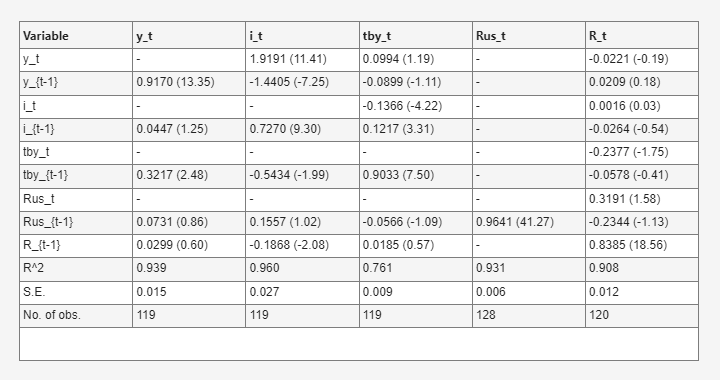

figure_table61(rownames, colnames, coefmat_BR, tstatmat_BR, r2vec_BR, sevec_BR, nobsvec_BR, 'Table 6.1.BR');

*Notes on this table vs. the panel versions:*  * N ~ 119-120 for equations 1/2/3/5, and N=128 for the Rus AR(1)

## Section 3: Impulse Response Functions (Table 6.1.BR data)

Same Cholesky-recursive construction as every other table in this series: A*z_t = B*z_{t-1} + eps_t, z_t = [y_t, i_t, tby_t, Rus_t, R_t]'.

[A, B] = build_AB(b1, b2, b3, b5, b_ar1_BR);
Ainv = inv(A); 
Phi  = Ainv * B;
maxeig = max(abs(eig(Phi)));
fprintf('\nTable 6.1.BR system: max|eigenvalue(Phi)| = %.4f %s\n', maxeig, ...
    ternary(maxeig>1.001, '(UNSTABLE)', '(stable)'));


Table 6.1.BR system: max|eigenvalue(Phi)| = 0.9641 (stable)


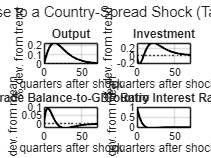


Hmax = 72;
irf_spread = compute_irf(Ainv, Phi, 5, Hmax);
irf_usrate = compute_irf(Ainv, Phi, 4, Hmax);
hz = (0:Hmax)';

figure('Name','IRF.BR to Country-Spread Shock (Table 6.1.BR)','Position',[100 100 800 600]);
subplot(2,2,1); plot(hz, irf_spread(:,1),'k-','LineWidth',1.5); yline(0,'k:');
title('Output'); xlabel('quarters after shock'); ylabel('% dev. from trend'); grid on;
subplot(2,2,2); plot(hz, irf_spread(:,2),'k-','LineWidth',1.5); yline(0,'k:');
title('Investment'); xlabel('quarters after shock'); ylabel('% dev. from trend'); grid on;
subplot(2,2,3); plot(hz, irf_spread(:,3),'k-','LineWidth',1.5); yline(0,'k:');
title('Trade Balance-to-GDP Ratio'); xlabel('quarters after shock'); ylabel('dev. from mean'); grid on;
subplot(2,2,4); plot(hz, irf_spread(:,5),'k-','LineWidth',1.5); yline(0,'k:');
title('Country Interest Rate'); xlabel('quarters after shock'); ylabel('dev. from mean'); grid on;
sgtitle('Impulse Response to a Country-Spread Shock (Table 6.1.BR data)');

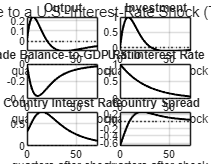


spread_irf = irf_usrate(:,5) - irf_usrate(:,4);
figure('Name','IRF.BR to US-Interest-Rate Shock (Table 6.1.BR)','Position',[100 100 900 700]);
subplot(3,2,1); plot(hz, irf_usrate(:,1),'k-','LineWidth',1.5); yline(0,'k:');
title('Output'); xlabel('quarters after shock'); grid on;
subplot(3,2,2); plot(hz, irf_usrate(:,2),'k-','LineWidth',1.5); yline(0,'k:');
title('Investment'); xlabel('quarters after shock'); grid on;
subplot(3,2,3); plot(hz, irf_usrate(:,3),'k-','LineWidth',1.5); yline(0,'k:');
title('Trade Balance-to-GDP Ratio'); xlabel('quarters after shock'); grid on;
subplot(3,2,4); plot(hz, irf_usrate(:,4),'k-','LineWidth',1.5); yline(0,'k:');
title('U.S. Interest Rate'); xlabel('quarters after shock'); grid on;
subplot(3,2,5); plot(hz, irf_usrate(:,5),'k-','LineWidth',1.5); yline(0,'k:');
title('Country Interest Rate'); xlabel('quarters after shock'); grid on;
subplot(3,2,6); plot(hz, spread_irf,'k-','LineWidth',1.5); yline(0,'k:');
title('Country Spread'); xlabel('quarters after shock'); grid on;
sgtitle('Impulse Response to a U.S.-Interest-Rate Shock (Table 6.1.BR data)');

## Local functions

function xl = simple_lag(x, n)

n-th lag of a single (already time-sorted, contiguous-quarter) series.

    xl = nan(size(x));
    xl(n+1:end) = x(1:end-n);
end

function [beta, se, resid, r2] = ols_iv(y, exog_cell, endog, instr, names, eqname)

2SLS with intercept, single time series (no cross-sectional demeaning -- there's only one country here, so an intercept does the same job).

    allvars = [{y, endog, instr}, exog_cell];
    samp = true(size(y));
    for k = 1:numel(allvars)
        samp = samp & ~isnan(allvars{k});
    end
    ys = y(samp); endogs = endog(samp); instrs = instr(samp);
    exogs = cellfun(@(v) v(samp), exog_cell, 'UniformOutput', false);

    if isempty(exogs)
        X = [ones(sum(samp),1), endogs];
        Z = [ones(sum(samp),1), instrs];
    else
        X = [ones(sum(samp),1), horzcat(exogs{:}), endogs];
        Z = [ones(sum(samp),1), horzcat(exogs{:}), instrs];
    end

    PZ    = Z*pinv(Z'*Z)*Z';
    Xhat  = PZ*X;
    beta_full = pinv(Xhat'*X)*(Xhat'*ys);
    resid = ys - X*beta_full;
    beta  = beta_full(2:end);   % drop intercept for the returned vector (matches names layout)

    n = size(X,1); k = size(X,2);
    dof = max(n-k, 1);
    sigma2 = (resid'*resid)/dof;
    varb = sigma2*pinv(Xhat'*X);
    se_full = sqrt(diag(varb));
    se = se_full(2:end);

    r2 = 1 - sum(resid.^2) / sum((ys - mean(ys)).^2);



=== BRAZIL ONLY, 1996:Q1-2026:Q1 -- reference residual s.d. check ===


    if nargin < 6, eqname = ''; end

  R equation:   Brazil = 0.0123,  paper (eq. 13, 1994-2001 panel) = 0.031


    fprintf('\n-- Equation [%s], n=%d, k=%d (incl. intercept), R^2=%.3f --\n', eqname, n, k, r2);

  Rus AR(1):    Brazil = 0.0059,  paper (eq. 15, 1987-2002 US-only) = 0.007


    for j = 1:numel(beta)

(Differences are expected: this is a single country over a much longer,


        lbl = '?'; if j<=numel(names), lbl = names{j}; end

 more recent, and more volatile sample than either of the paper's own.)


        fprintf('   %-18s coef=% .4f  se=%.4f  t=% .2f\n', lbl, beta(j), se(j), beta(j)/se(j));
    end
end

function [colcoef, coltstat] = map_to_rows(names, beta, se, rowmap)
    colcoef = nan(9,1); coltstat = nan(9,1);
    for j = 1:numel(names)
        nm = strrep(names{j}, '(IV)', '');
        if isKey(rowmap, nm)
            r = rowmap(nm);
            colcoef(r)  = beta(j);


Saved 8 target IRFs (4 variables x 2 shocks x 24 quarters = 192 points)


            coltstat(r) = beta(j)/se(j);

to IRF_target_uribe_yue_Brazil.mat  (Brazil only, 1996:Q1-2026:Q1)


        end
    end
end

function print_table61(rownames, colnames, coef, tstat, r2, se_eq, nobs)
    fprintf('\n%-12s', 'Variable');
    for c = 1:numel(colnames), fprintf('%12s', colnames{c}); end
    fprintf('\n');
    for rr = 1:numel(rownames)
        fprintf('%-12s', rownames{rr});
        for c = 1:size(coef,2)
            if isnan(coef(rr,c)), fprintf('%12s', '-');
            else, fprintf('%12.4f', coef(rr,c)); end
        end
        fprintf('\n%-12s', '');
        for c = 1:size(coef,2)
            if isnan(tstat(rr,c)), fprintf('%12s', '');
            else, fprintf('%12s', sprintf('(%.2f)', tstat(rr,c))); end
        end
        fprintf('\n');
    end
    fprintf('%-12s', 'R^2');
    for c = 1:numel(r2), fprintf('%12.3f', r2(c)); end
    fprintf('\n%-12s', 'S.E.');
    for c = 1:numel(se_eq), fprintf('%12.3f', se_eq(c)); end
    fprintf('\n%-12s', 'No. of obs.');
    for c = 1:numel(nobs), fprintf('%12d', nobs(c)); end
    fprintf('\n');
end

function figure_table61(rownames, colnames, coef, tstat, r2, se_eq, nobs, titlestr)
    if nargin < 8, titlestr = 'Table 6.1'; end
    nR = numel(rownames); nC = numel(colnames);


-- Equation [y.BR.alt], n=119, k=8 (incl. intercept), R^2=0.937 --
   loginvdsalag       coef= 0.0470  se=0.0378  t= 1.24
   tbysalag           coef= 0.2915  se=0.1803  t= 1.62
   logruslag          coef= 0.0100  se=0.3179  t= 0.03
   logrus(NEW)        coef= 0.0837  se=0.3686  t= 0.23
   logilag            coef= 0.2046  se=0.7158  t= 0.29
   logi(NEW,IV)       coef=-0.2007  se=0.8207  t=-0.24
   logydsalag(IV)     coef= 0.9055  se=0.0844  t= 10.73


    data = cell(nR+3, nC+1);
    data(1:nR,1) = rownames(:);
    data{nR+1,1} = 'R^2';
    data{nR+2,1} = 'S.E.';
    data{nR+3,1} = 'No. of obs.';
    for c = 1:nC


-- Equation [i.BR.alt], n=119, k=9 (incl. intercept), R^2=0.948 --
   logydsa            coef= 1.9006  se=0.1937  t= 9.81
   logydsalag         coef=-1.4524  se=0.2275  t=-6.38
   tbysalag           coef=-0.1737  se=0.4773  t=-0.36
   logruslag          coef= 1.1691  se=0.6354  t= 1.84
   logrus(NEW)        coef=-1.1650  se=0.7230  t=-1.61
   logilag            coef=-1.4529  se=1.4133  t=-1.03
   logi(NEW,IV)       coef= 1.4593  se=1.6235  t= 0.90
   loginvdsalag(IV)   coef= 0.7684  se=0.0963  t= 7.98


        for r = 1:nR
            if isnan(coef(r,c))
                data{r,c+1} = '-';
            else
                data{r,c+1} = sprintf('%.4f (%.2f)', coef(r,c), tstat(r,c));
            end


-- Equation [tb/y.BR.alt], n=119, k=10 (incl. intercept), R^2=0.434 --
   logydsa            coef= 0.1547  se=0.1390  t= 1.11
   logydsalag         coef=-0.1349  se=0.1338  t=-1.01
   loginvdsa          coef=-0.1702  se=0.0604  t=-2.82
   loginvdsalag       coef= 0.1622  se=0.0735  t= 2.21
   logruslag          coef= 0.2200  se=0.3196  t= 0.69
   logrus(NEW)        coef=-0.3383  se=0.3581  t=-0.94
   logilag            coef=-0.6190  se=0.6843  t=-0.90
   logi(NEW,IV)       coef= 0.7282  se=0.7854  t= 0.93
   tbysalag(IV)       coef= 1.0572  se=0.2690  t= 3.93


        end
        data{nR+1,c+1} = sprintf('%.3f', r2(c));
        data{nR+2,c+1} = sprintf('%.3f', se_eq(c));
        data{nR+3,c+1} = sprintf('%d', nobs(c));
    end
    fig = uifigure('Name', titlestr, 'Position', [100 100 720 380]);
    uitable(fig, 'Data', data, ...
        'ColumnName', [{'Variable'}, colnames], ...
        'RowName', {}, ...
        'Position', [20 20 680 340]);
end


============ Contemporaneous R_t coefficient, relaxed scheme ============


(coefficient on same-quarter R_t added to each real-variable equation)



function [A, B] = build_AB(b1, b2, b3, b5, rho_rus)
    A = eye(5);
    B = zeros(5,5);
    B(1,2)=b1(1); B(1,3)=b1(2); B(1,4)=b1(3); B(1,5)=b1(4); B(1,1)=b1(5);

  y_t   equation: coef=-0.2007  se=0.8207  t=-0.24


    A(2,1) = -b2(1);

  i_t   equation: coef= 1.4593  se=1.6235  t= 0.90


    B(2,1)=b2(2); B(2,3)=b2(3); B(2,4)=b2(4); B(2,5)=b2(5); B(2,2)=b2(6);

  tby_t equation: coef= 0.7282  se=0.7854  t= 0.93


    A(3,1) = -b3(1); A(3,2) = -b3(3);


(economically: a country-rate INCREASE should, if anything, contract y_t/i_t


    B(3,1)=b3(2); B(3,2)=b3(4); B(3,4)=b3(5); B(3,5)=b3(6); B(3,3)=b3(7);

 contemporaneously and improve tby_t -- i.e. expect coef<0 for y_t/i_t and >0


    B(4,4) = rho_rus;

 for tby_t. A wrong-signed or insignificant estimate here is the same kind of


    A(5,1) = -b5(1); A(5,2) = -b5(3); A(5,3) = -b5(5); A(5,4) = -b5(7);

 evidence the paper itself uses to prefer the baseline lagged-only scheme.)


    B(5,1)=b5(2); B(5,2)=b5(4); B(5,3)=b5(6); B(5,4)=b5(8); B(5,5)=b5(9);
end

function IRF = compute_irf(Ainv, Phi, shock_idx, H)
    e = zeros(5,1); e(shock_idx) = 1;
    z = Ainv * e;
    IRF = z';
    for h = 1:H
        z = Phi * z;


Alternative-scheme system: max|eigenvalue(Phi)| = 0.9641 (stable)


        IRF = [IRF; z']; 
    end
end

function out = ternary(cond, a, b)
    if cond, out = a; else, out = b; end
end

## Export target IRFs for Dynare IRF matching -- BRAZIL ONLY

 Produces a single .mat file that DSGE_uribe_yue_IRFmatch_Brazil.mod loads through its matched_irfs; block.

- **Brazil-only sample: **1996:Q1 - 2026:Q1 (Table 6.1.BR). 

- Same normalization as the baseline export (uribe_yue_VAR_target_export.m), matching Uribe and Yue (2006, JIE), Section 3.1.4's own methodology:  "we consider the first 24 quarters of the impulse response functions   of 4 variables (output, investment, the trade balance, and the country interest rate), to 2 shocks (the US-interest-rate shock and the   country-spread shock). Thus, we are setting 4 parameter values to  match 192 points." (4 vars x 2 shocks x 24 quarters = 192)

- **Only 4 variables are matched: **y, i, tby, R (not Rus)

- **Shock size** is 0.01, NOT a one-standard-deviation shock 

- Build the 4-variable, 24-quarter target, at the paper's 0.01 shock size

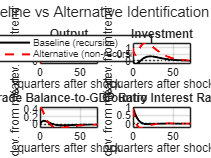

SHOCK_SIZE = 0.01;   % matches "unit innovation" / "one percentage point increase"
HORIZON    = 24;     % "the first 24 quarters" -- rows 1:24 of irf_spread/irf_usrate
                      % (row 1 = impact = horizon 0, matching Dynare's own
                      % oo_.irfs indexing convention). Independent of
                      % whatever Hmax your Section 3 plots use.

if size(irf_spread,1) < HORIZON || size(irf_usrate,1) < HORIZON
    error('irf_spread/irf_usrate have fewer than %d rows -- increase Hmax in Section 3 first.', HORIZON);
end

% Column mapping in irf_spread / irf_usrate: [y, i, tby, rus, R]
%   column 1 -> yy (output)     column 2 -> iv (investment)
%   column 3 -> tby             column 5 -> r (country rate)
%   (column 4, rus, is intentionally skipped -- not a matched variable)
% Shock mapping: irf_spread (shock to the R equation) -> Dynare's eps_r
%                irf_usrate (shock to the Rus equation) -> Dynare's eps_rus

yy_eps_r  = irf_spread(1:HORIZON,1) * SHOCK_SIZE;
iv_eps_r  = irf_spread(1:HORIZON,2) * SHOCK_SIZE;
tby_eps_r = irf_spread(1:HORIZON,3) * SHOCK_SIZE;
r_eps_r   = irf_spread(1:HORIZON,5) * SHOCK_SIZE;

yy_eps_rus  = irf_usrate(1:HORIZON,1) * SHOCK_SIZE;

iv_eps_rus  = irf_usrate(1:HORIZON,2) * SHOCK_SIZE;
tby_eps_rus = irf_usrate(1:HORIZON,3) * SHOCK_SIZE;
r_eps_rus   = irf_usrate(1:HORIZON,5) * SHOCK_SIZE;

%% Reference only: this replication's own empirical shock s.d.'s
% NOT used for the matching itself (the paper's stated 0.031 / 0.007 are
% hardcoded directly in the .mod file's shocks; block instead) -- kept
% here purely for comparison against the ORIGINAL paper's reported values
% and against the baseline panel replication's own sevec_A estimates.

se_r_replication_estimate   = sevec_BR(5);   % R equation residual s.d., Brazil only
se_rus_replication_estimate = sevec_BR(4);   % Rus AR(1) residual s.d., Brazil only

fprintf('\n=== BRAZIL ONLY, 1996:Q1-2026:Q1 -- reference residual s.d. check ===\n');
fprintf('  R equation:   Brazil = %.4f,  paper (eq. 13, 1994-2001 panel) = 0.031\n', se_r_replication_estimate);
fprintf('  Rus AR(1):    Brazil = %.4f,  paper (eq. 15, 1987-2002 US-only) = 0.007\n', se_rus_replication_estimate);
fprintf('(Differences are expected: this is a single country over a much longer,\n');
fprintf(' more recent, and more volatile sample than either of the paper''s own.)\n');

%% Save -- to a BRAZIL-SPECIFIC filename, distinct from the baseline target

save('IRF_target_uribe_yue_Brazil.mat', ...
    'yy_eps_r','iv_eps_r','tby_eps_r','r_eps_r', ...
    'yy_eps_rus','iv_eps_rus','tby_eps_rus','r_eps_rus', ...
    'SHOCK_SIZE','HORIZON', ...
    'se_r_replication_estimate','se_rus_replication_estimate','hz');

fprintf('\nSaved 8 target IRFs (4 variables x 2 shocks x %d quarters = %d points)\n', ...
    HORIZON, 4*2*HORIZON);
fprintf('to IRF_target_uribe_yue_Brazil.mat  (Brazil only, 1996:Q1-2026:Q1)\n');


## Section 3d: Alternative identification -- relaxing same-quarter exogeneity

*** BRAZIL ONLY. Sample: 1996:Q1 - 2026:Q1.

WHY THIS SECTION EXISTS: the baseline identification (Sections 2-3) assumes country-spread/world-rate innovations take one quarter to reach real domestic variables -- y_t, i_t, tby_t never see Rus_t or R_t

contemporaneously, only lagged (that's what makes the recursive/Cholesky ordering [y,i,tby,Rus,R] deliver a clean identification). Uribe and Yue (2006, JIE) note they tested an alternative scheme relaxing exactly this, in their working-paper appendix (Uribe and Yue, 2003, NBER WP 10018) --

not shown in the published paper's equations, only described in prose: "we explore an identification scheme that allows for real domestic variables to react contemporaneously to innovations in the US interest rate or the country spread." They report the resulting impact effect of a US-rate shock on output/investment came out "slightly positive," with two-standard-error bands including zero, and concluded their maintained (recursive) identification was more plausible.

#### **Reconstruction used here:**

- Rus_t is added as a plain contemporaneous regressor to the y, i, tby

  equations. No instrument needed -- Rus is the US rate, plausibly

  exogenous to Brazil regardless of timing, and the paper's OWN

  restriction that Rus follows a pure AR(1) (unaffected by anything in

  the panel) is kept unchanged here for the same reason.

- R_t (the country rate) is added as an INSTRUMENTED, ENDOGENOUS

  contemporaneous regressor to the y, i, tby equations, instrumented by

  R_{t-2} (R_{t-1} is already an included control, so a deeper lag is

  needed as the excluded instrument). This is the genuinely new,

  non-recursive piece: R_t can now affect y_t/i_t/tby_t contemporaneously,

  AND (unchanged from the baseline) y_t/i_t/tby_t still affect R_t

  contemporaneously via R's own equation -- true two-way simultaneity,

  identified only because R_{t-2} is assumed uncorrelated with this

  quarter's y/i/tby innovations.

- R's own equation (eq. 5) and the Rus AR(1) (eq. 4) are UNCHANGED --

  the relaxation only concerns whether y/i/tby can see R contemporane-

  ously, not the reverse (R already saw everything in the baseline).

- Re-estimate y, i, tby allowing contemporaneous Rus_t and (instrumented) R_t

- Uses a NEW local function, ols_iv_multi, which generalizes ols_iv to support more than one endogenous/instrumented regressor per equation (needed here: each equation now has TWO endogenous regressors -- its own lag, as before, AND the new contemporaneous R_t).

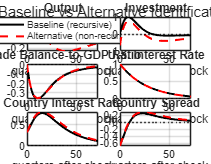

[b1_alt, se1_alt, res1_alt, r2_1_alt] = ols_iv_multi(logydsa, ...
    {loginvdsalag, tbysalag, logruslag, logrus, logilag}, ...
    {logi, logydsalag}, {logilag2, logydsalag2}, ...
    {'loginvdsalag','tbysalag','logruslag','logrus(NEW)','logilag', ...
     'logi(NEW,IV)','logydsalag(IV)'}, 'y.BR.alt');


[b2_alt, se2_alt, res2_alt, r2_2_alt] = ols_iv_multi(loginvdsa, ...
    {logydsa, logydsalag, tbysalag, logruslag, logrus, logilag}, ...
    {logi, loginvdsalag}, {logilag2, loginvdsalag2}, ...
    {'logydsa','logydsalag','tbysalag','logruslag','logrus(NEW)','logilag', ...
     'logi(NEW,IV)','loginvdsalag(IV)'}, 'i.BR.alt');

[b3_alt, se3_alt, res3_alt, r2_3_alt] = ols_iv_multi(tbysa, ...
    {logydsa, logydsalag, loginvdsa, loginvdsalag, logruslag, logrus, logilag}, ...
    {logi, tbysalag}, {logilag2, tbysalag2}, ...
    {'logydsa','logydsalag','loginvdsa','loginvdsalag','logruslag','logrus(NEW)','logilag', ...
     'logi(NEW,IV)','tbysalag(IV)'}, 'tb/y.BR.alt');

% eq. 5 (R_t) and eq. 4 (Rus AR(1)) are UNCHANGED -- reuse b5, b_ar1_BR
% from Section 2 directly, no re-estimation.

%% Plausibility check: sign and significance of the NEW contemporaneous R_t terms
% This mirrors what the paper itself checks in its own version of this
% exercise -- if the new same-quarter R_t coefficients come out with an
% implausible sign or are statistically indistinguishable from zero, that
% is evidence FOR the baseline (lagged-only) identification, not against it.

fprintf('\n============ Contemporaneous R_t coefficient, relaxed scheme ============\n');
fprintf('(coefficient on same-quarter R_t added to each real-variable equation)\n\n');
r_t_coef_y   = b1_alt(6);  r_t_se_y   = se1_alt(6);
r_t_coef_i   = b2_alt(7);  r_t_se_i   = se2_alt(7);
r_t_coef_tby = b3_alt(8);  r_t_se_tby = se3_alt(8);
fprintf('  y_t   equation: coef=% .4f  se=%.4f  t=% .2f\n', r_t_coef_y,   r_t_se_y,   r_t_coef_y/r_t_se_y);
fprintf('  i_t   equation: coef=% .4f  se=%.4f  t=% .2f\n', r_t_coef_i,   r_t_se_i,   r_t_coef_i/r_t_se_i);
fprintf('  tby_t equation: coef=% .4f  se=%.4f  t=% .2f\n', r_t_coef_tby, r_t_se_tby, r_t_coef_tby/r_t_se_tby);
fprintf('\n(economically: a country-rate INCREASE should, if anything, contract y_t/i_t\n');
fprintf(' contemporaneously and improve tby_t -- i.e. expect coef<0 for y_t/i_t and >0\n');
fprintf(' for tby_t. A wrong-signed or insignificant estimate here is the same kind of\n');
fprintf(' evidence the paper itself uses to prefer the baseline lagged-only scheme.)\n');

%% Build the non-recursive A, B matrices and compute IRFs

[A_alt, B_alt] = build_AB_alt(b1_alt, b2_alt, b3_alt, b5, b_ar1_BR);
Ainv_alt = inv(A_alt); %#ok<MINV>
Phi_alt  = Ainv_alt * B_alt;
maxeig_alt = max(abs(eig(Phi_alt)));
fprintf('\nAlternative-scheme system: max|eigenvalue(Phi)| = %.4f %s\n', maxeig_alt, ...
    ternary(maxeig_alt>1.001, '(UNSTABLE)', '(stable)'));

Hmax_alt = 72;   % matches Section 3's horizon
irf_spread_alt = compute_irf(Ainv_alt, Phi_alt, 5, Hmax_alt);
irf_usrate_alt = compute_irf(Ainv_alt, Phi_alt, 4, Hmax_alt);
hz_alt = (0:Hmax_alt)';

%% Plot: baseline (recursive) vs. alternative (non-recursive) identification, overlaid
% Two lines per panel -- if the identifying assumption matters for the
% conclusions, the lines should visibly diverge; if it doesn't, they
% should sit close together.

figure('Name','BRAZIL: Baseline vs Alternative Identification -- Country-Spread Shock','Position',[100 100 800 600]);
subplot(2,2,1)
plot(hz, irf_spread(:,1),'k-','LineWidth',1.5); hold on;
plot(hz_alt, irf_spread_alt(:,1),'r--','LineWidth',1.5); yline(0,'k:');
title('Output'); xlabel('quarters after shock'); ylabel('% dev. from trend'); grid on;
legend({'Baseline (recursive)','Alternative (non-recursive)'},'Location','best')

subplot(2,2,2)
plot(hz, irf_spread(:,2),'k-','LineWidth',1.5); hold on;
plot(hz_alt, irf_spread_alt(:,2),'r--','LineWidth',1.5); yline(0,'k:');
title('Investment'); xlabel('quarters after shock'); ylabel('% dev. from trend'); grid on;

subplot(2,2,3)
plot(hz, irf_spread(:,3),'k-','LineWidth',1.5); hold on;
plot(hz_alt, irf_spread_alt(:,3),'r--','LineWidth',1.5); yline(0,'k:');
title('Trade Balance-to-GDP Ratio'); xlabel('quarters after shock'); ylabel('dev. from mean'); grid on;

subplot(2,2,4)
plot(hz, irf_spread(:,5),'k-','LineWidth',1.5); hold on;
plot(hz_alt, irf_spread_alt(:,5),'r--','LineWidth',1.5); yline(0,'k:');
title('Country Interest Rate'); xlabel('quarters after shock'); ylabel('dev. from mean'); grid on;

sgtitle('BRAZIL, 1996-2026: Baseline vs Alternative Identification -- Country-Spread Shock');

figure('Name','BRAZIL: Baseline vs Alternative Identification -- US-Rate Shock','Position',[100 100 900 700]);
spread_irf_alt = irf_usrate_alt(:,5) - irf_usrate_alt(:,4);

subplot(3,2,1)
plot(hz, irf_usrate(:,1),'k-','LineWidth',1.5); hold on;
plot(hz_alt, irf_usrate_alt(:,1),'r--','LineWidth',1.5); yline(0,'k:');
title('Output'); xlabel('quarters after shock'); grid on;
legend({'Baseline (recursive)','Alternative (non-recursive)'},'Location','best')

subplot(3,2,2)
plot(hz, irf_usrate(:,2),'k-','LineWidth',1.5); hold on;
plot(hz_alt, irf_usrate_alt(:,2),'r--','LineWidth',1.5); yline(0,'k:');
title('Investment'); xlabel('quarters after shock'); grid on;

subplot(3,2,3)
plot(hz, irf_usrate(:,3),'k-','LineWidth',1.5); hold on;
plot(hz_alt, irf_usrate_alt(:,3),'r--','LineWidth',1.5); yline(0,'k:');
title('Trade Balance-to-GDP Ratio'); xlabel('quarters after shock'); grid on;

subplot(3,2,4)
plot(hz, irf_usrate(:,4),'k-','LineWidth',1.5); hold on;
plot(hz_alt, irf_usrate_alt(:,4),'r--','LineWidth',1.5); yline(0,'k:');
title('U.S. Interest Rate'); xlabel('quarters after shock'); grid on;

subplot(3,2,5)
plot(hz, irf_usrate(:,5),'k-','LineWidth',1.5); hold on;
plot(hz_alt, irf_usrate_alt(:,5),'r--','LineWidth',1.5); yline(0,'k:');
title('Country Interest Rate'); xlabel('quarters after shock'); grid on;

subplot(3,2,6)
plot(hz, spread_irf,'k-','LineWidth',1.5); hold on;
plot(hz_alt, spread_irf_alt,'r--','LineWidth',1.5); yline(0,'k:');
title('Country Spread'); xlabel('quarters after shock'); grid on;

sgtitle('BRAZIL, 1996-2026: Baseline vs Alternative Identification -- US-Rate Shock');

%% Local functions (append these to the existing "Local functions" section)

function [beta, se, resid, r2] = ols_iv_multi(y, exog_cell, endog_cell, instr_cell, names, eqname)
% Generalizes ols_iv to support MULTIPLE endogenous/instrumented
% regressors (ols_iv only supports exactly one). endog_cell and
% instr_cell must have the same length, with instr_cell{k} the instrument
% for endog_cell{k}. Otherwise identical logic to ols_iv: 2SLS with
% intercept, single time series.
    if numel(endog_cell) ~= numel(instr_cell)
        error('ols_iv_multi: endog_cell and instr_cell must have the same length.');
    end
    allvars = [{y}, exog_cell, endog_cell, instr_cell];
    samp = true(size(y));
    for k = 1:numel(allvars)
        samp = samp & ~isnan(allvars{k});
    end
    ys = y(samp);
    exogs  = cellfun(@(v) v(samp), exog_cell,  'UniformOutput', false);
    endogs = cellfun(@(v) v(samp), endog_cell, 'UniformOutput', false);
    instrs = cellfun(@(v) v(samp), instr_cell, 'UniformOutput', false);

    if isempty(exogs)
        X = [ones(sum(samp),1), horzcat(endogs{:})];
        Z = [ones(sum(samp),1), horzcat(instrs{:})];
    else
        X = [ones(sum(samp),1), horzcat(exogs{:}), horzcat(endogs{:})];
        Z = [ones(sum(samp),1), horzcat(exogs{:}), horzcat(instrs{:})];
    end

    PZ    = Z*pinv(Z'*Z)*Z';
    Xhat  = PZ*X;
    beta_full = pinv(Xhat'*X)*(Xhat'*ys);
    resid = ys - X*beta_full;
    beta  = beta_full(2:end);

    n = size(X,1); k = size(X,2);
    dof = max(n-k, 1);
    sigma2 = (resid'*resid)/dof;
    varb = sigma2*pinv(Xhat'*X);
    se_full = sqrt(diag(varb));
    se = se_full(2:end);

    r2 = 1 - sum(resid.^2) / sum((ys - mean(ys)).^2);

    if nargin < 6, eqname = ''; end
    fprintf('\n-- Equation [%s], n=%d, k=%d (incl. intercept), R^2=%.3f --\n', eqname, n, k, r2);
    for j = 1:numel(beta)
        lbl = '?'; if j<=numel(names), lbl = names{j}; end
        fprintf('   %-18s coef=% .4f  se=%.4f  t=% .2f\n', lbl, beta(j), se(j), beta(j)/se(j));
    end
end

function [A, B] = build_AB_alt(b1, b2, b3, b5, rho_rus)
% Non-recursive version of build_AB: y, i, tby now also depend on
% CONTEMPORANEOUS R_t (A(1,5), A(2,5), A(3,5) all nonzero, unlike the
% baseline's strictly triangular A), on top of R's own equation still
% depending on contemporaneous y, i, tby, Rus (A(5,1:4), unchanged from
% the baseline) -- genuine two-way simultaneity between R and {y,i,tby}.
% Coefficient vector layouts (see the ols_iv_multi calls above):
%   b1 = [i_{t-1}, tby_{t-1}, Rus_{t-1}, Rus_t, R_{t-1}, R_t(endog), y_{t-1}(endog)]
%   b2 = [y_t, y_{t-1}, tby_{t-1}, Rus_{t-1}, Rus_t, R_{t-1}, R_t(endog), i_{t-1}(endog)]
%   b3 = [y_t, y_{t-1}, i_t, i_{t-1}, Rus_{t-1}, Rus_t, R_{t-1}, R_t(endog), tby_{t-1}(endog)]
%   b5 = UNCHANGED from build_AB: [y_t,y_{t-1},i_t,i_{t-1},tby_t,tby_{t-1},Rus_t,Rus_{t-1},R_{t-1}(endog)]
    A = eye(5);
    B = zeros(5,5);

    % row 1: y_t
    A(1,4) = -b1(4);   % NEW: y sees Rus_t contemporaneously
    A(1,5) = -b1(6);   % NEW: y sees R_t contemporaneously (endogenous, instrumented)
    B(1,2) = b1(1); B(1,3) = b1(2); B(1,4) = b1(3); B(1,5) = b1(5);
    B(1,1) = b1(7);    % y_{t-1}, endogenous own lag

    % row 2: i_t
    A(2,1) = -b2(1);   % unchanged: i sees y_t contemporaneously
    A(2,4) = -b2(5);   % NEW: i sees Rus_t contemporaneously
    A(2,5) = -b2(7);   % NEW: i sees R_t contemporaneously (endogenous)
    B(2,1) = b2(2); B(2,3) = b2(3); B(2,4) = b2(4); B(2,5) = b2(6);
    B(2,2) = b2(8);    % i_{t-1}, endogenous own lag

    % row 3: tby_t
    A(3,1) = -b3(1); A(3,2) = -b3(3);   % unchanged: tby sees y_t, i_t contemporaneously
    A(3,4) = -b3(6);   % NEW: tby sees Rus_t contemporaneously
    A(3,5) = -b3(8);   % NEW: tby sees R_t contemporaneously (endogenous)
    B(3,1) = b3(2); B(3,2) = b3(4); B(3,4) = b3(5); B(3,5) = b3(7);
    B(3,3) = b3(9);    % tby_{t-1}, endogenous own lag

    % row 4: Rus_t -- UNCHANGED, restricted AR(1)
    B(4,4) = rho_rus;

    % row 5: R_t -- UNCHANGED from the baseline (already saw everything contemporaneously)
    A(5,1) = -b5(1); A(5,2) = -b5(3); A(5,3) = -b5(5); A(5,4) = -b5(7);
    B(5,1) = b5(2); B(5,2) = b5(4); B(5,3) = b5(6); B(5,4) = b5(8);
    B(5,5) = b5(9);    % R_{t-1}, endogenous own lag
end
